clearvars;

Data construction

N = 5000; % Number of points
t = linspace(0,5,N)'; % Time vector with fs = 500 Hz

a= 0.75;
phi = 0;
snr = 10;

s = sawtooth(2*pi*2*t(1:N,1),0.5); % Sawtooth signal
n1 = 0.2*sin(2*pi*50*t(1:N/2,1)-phi); % Sinusoid at 50 Hz
n2 = 0.3*sin(2* pi*100*t(N/2+1:N,1)-phi); % Sinusoid at 100 Hz
nwg = s - awgn(s,snr,'measured'); % Gaussian white noise

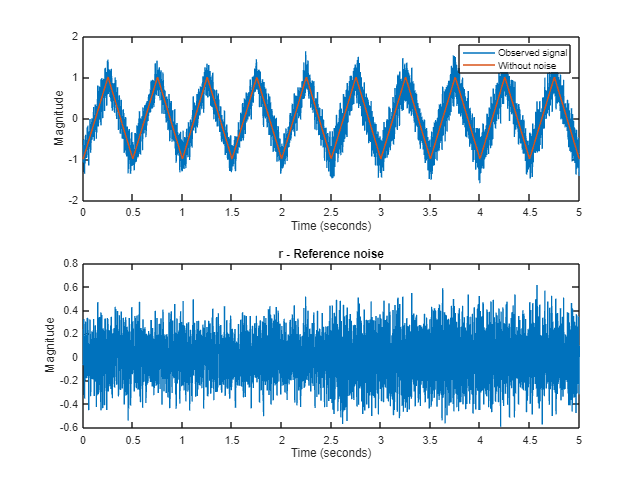

r = (nwg + [n1 ;n2])*a;
x = s+nwg + [n1 ;n2];

figure('Position', [100, 100, 800, 600]);
subplot(2, 1, 1); 
plot(t, x);
hold on;
plot(t, s);
legend("Observed signal","Without noise");
xlabel("Time (seconds)");
ylabel("Magnitude");

subplot(2, 1, 2); 
plot(t, r);
xlabel("Time (seconds)");
ylabel("Magnitude");
title("r - Reference noise");

LMS Method

power_x = sum(abs(x).^2) / length(x); %power of x
min_M = 3;
lambda_max = 20*min_M*power_x;   

miu_values = linspace(0.03,2/lambda_max,100);
error_matrix = zeros(length(3:20),length(linspace(0.3,2/lambda_max,100)));

best_M_LMS = 0;
best_miu = 0;
best_constructed_signal = [];
min_error = inf;

considered_M_LMS = [5,10,15];
considered_miu = [miu_values(30), miu_values(60), miu_values(90)];
considered_signal_outputs_LMS = {};
considered_MSE_LMS = [];

c = 1;
k = 0;
for M = 3:20
    w = rand(M,1);
    k = k + 1;
    
    for j=1:100;
        miu = miu_values(j);
        constructed_signal = [];
        for i=1:length(x)-M+1
            R = r(i:i+M-1);
            y = w'*R;
            e = x(i+M-1)-y;
            constructed_signal = [constructed_signal; e];
            w = w + 2*miu*e*R;
        end

        % error = sum((s(M:end) - constructed_signal).^2);
        error = immse(s(M:end),constructed_signal);
        error_matrix(k,j) = error;

        if ismember(M,considered_M_LMS) && ismember(miu,considered_miu)
            considered_signal_outputs_LMS{c} = constructed_signal;
            considered_MSE_LMS = [considered_MSE_LMS error];
            c = c+1;
        end

        if error < min_error
            min_error = error;
            best_constructed_signal = constructed_signal;
            best_M_LMS = M;
            best_miu = miu;
        end
    end
end

figure('Position', [100, 100, 800, 600]);

for row = 1:3
    for col = 1:3
        subplot(3,3,(row-1)*3+col);
        m = considered_M_LMS(row);
        mu = considered_miu(col);
        plot(t(m:end), considered_signal_outputs_LMS{(row-1)*3+col});
        hold on;
        plot(t(m:end), abs((s(m:end)-considered_signal_outputs_LMS{(row-1)*3+col}).^2));
        title(sprintf('Order=%d, \\mu = %.3f', m-1, mu));
        fprintf("Order = %d, mu = %.3f ---> Mean Square Error = %.5f\n",m-1,mu,considered_MSE_LMS((row-1)*3+col));
    end
end

Order = 4, mu = 0.046 ---> Mean Square Error = 0.00105
Order = 4, mu = 0.062 ---> Mean Square Error = 0.00156
Order = 4, mu = 0.078 ---> Mean Square Error = 0.00208
Order = 9, mu = 0.046 ---> Mean Square Error = 0.00181
Order = 9, mu = 0.062 ---> Mean Square Error = 0.00269
Order = 9, mu = 0.078 ---> Mean Square Error = 0.00363
Order = 14, mu = 0.046 ---> Mean Square Error = 0.00231
Order = 14, mu = 0.062 ---> Mean Square Error = 0.00360
Order = 14, mu = 0.078 ---> Mean Square Error = 0.00507


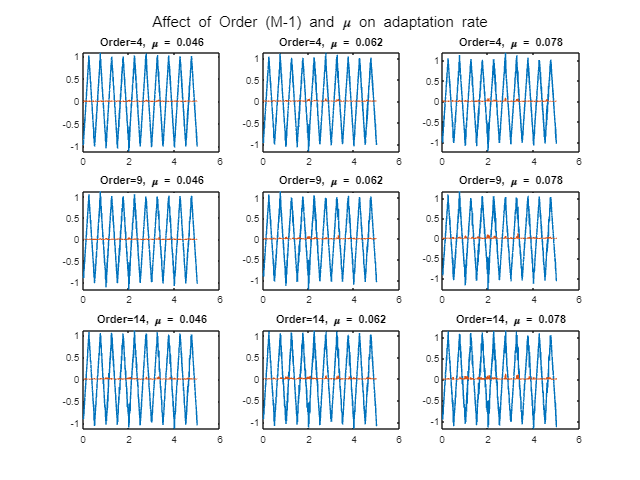

sgtitle("Affect of Order (M-1) and \mu on adaptation rate");

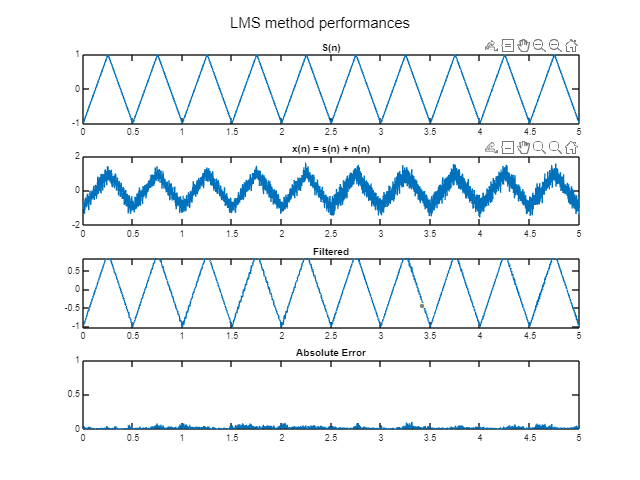

figure('Position', [100, 100, 800, 600]);
subplot(4, 1, 1); 
plot(t(best_M_LMS:end), s(best_M_LMS:end));
title("S(n)")

subplot(4, 1, 2); 
plot(t(best_M_LMS:end), x(best_M_LMS:end));
title("x(n) = s(n) + n(n)");

subplot(4, 1, 3); 
plot(t(best_M_LMS:end),best_constructed_signal);
title("Filtered");

subplot(4, 1, 4); 
plot(t(best_M_LMS:end), abs(s(best_M_LMS:end)-best_constructed_signal));
ylim([0 1]);
title("Absolute Error");

sgtitle("LMS method performances");

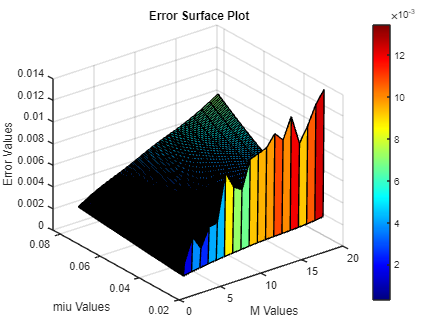


M_values = 3:20;

figure;
[M, Miu] = meshgrid(M_values, miu_values);
surf(M, Miu, error_matrix');

xlabel('M Values');
ylabel('miu Values');
zlabel('Error Values');
title('Error Surface Plot');
view(3);
colormap('jet');
colorbar;

RLS Method

delta = 1e-3;
lambdas = linspace(0.5,0.99,20);
errors_Matrix_RLS = zeros(length(3:20),20);

best_M_RLS = 0;
best_lambda = 0;
best_constructed_signal_RLS = [];
minimum_sqr_error_RLS = inf;

considered_M_RLS = [5,10,15];
considered_lambdas = [lambdas(15), lambdas(17), lambdas(20)];
considered_signal_outputs_RLS = {};
considered_MSE_RLS = [];

c=1;
k=0;
for M = 3:20
    k = k+1;
    for l = 1:20
        lambda = lambdas(l);

        p_n = ((lambda)^(-1))*eye(M);
        w_n = rand(M,1);
        % w_n = zeros(M,1);
        constructed_signal_RLS = [];

        for h = 1:length(x)-M+1
            R = r(h:h+M-1);

            k_n = ((lambda^-1)*p_n*R) / (1 + (lambda^-1)*R'*p_n*R);
            p_n = (lambda^-1)*p_n - (lambda^-1)*k_n*R'*p_n;
            alpha_n = x(h+M-1) - w_n'*R;
            w_n = w_n + k_n*alpha_n;
            constructed_signal_RLS = [constructed_signal_RLS; alpha_n];
        end
        
        % sqr_error_RLS = sum((x(M:end)-constructed_signal_RLS).^2);
        sqr_error_RLS = immse(x(M:end),constructed_signal_RLS);
        errors_Matrix_RLS(k,l) = sqr_error_RLS;

        if ismember(M,considered_M_RLS) && ismember(lambda,considered_lambdas)
            considered_signal_outputs_RLS{c} = constructed_signal_RLS;
            considered_MSE_RLS = [considered_MSE_RLS sqr_error_RLS];
            c = c+1;
        end

        if sqr_error_RLS < minimum_sqr_error_RLS
            best_M_RLS = M;
            best_lambda = lambda;
            best_constructed_signal_RLS = constructed_signal_RLS;
            minimum_sqr_error_RLS = sqr_error_RLS;
        end
    end
end

figure('Position', [100, 100, 800, 600]);

for row = 1:3
    for col = 1:3
        subplot(3,3,(row-1)*3+col);
        m = considered_M_RLS(row);
        lam = considered_lambdas(col);
        plot(t(m:end), considered_signal_outputs_RLS{(row-1)*3+col});
        hold on;
        plot(t(m:end), abs((s(m:end)-considered_signal_outputs_RLS{(row-1)*3+col}).^2));
        title(sprintf('Order=%d, \\lambda = %.3f', m-1, lam));
        fprintf("Order = %d, lambda = %.3f ---> Mean Square Error = %.5f\n",m-1,lam,considered_MSE_RLS((row-1)*3+col));

    end
end

Order = 4, lambda = 0.861 ---> Mean Square Error = 0.14177
Order = 4, lambda = 0.913 ---> Mean Square Error = 0.10297
Order = 4, lambda = 0.990 ---> Mean Square Error = 0.06792
Order = 9, lambda = 0.861 ---> Mean Square Error = 0.30236
Order = 9, lambda = 0.913 ---> Mean Square Error = 0.18155
Order = 9, lambda = 0.990 ---> Mean Square Error = 0.07406
Order = 14, lambda = 0.861 ---> Mean Square Error = 0.51037
Order = 14, lambda = 0.913 ---> Mean Square Error = 0.27460
Order = 14, lambda = 0.990 ---> Mean Square Error = 0.08055


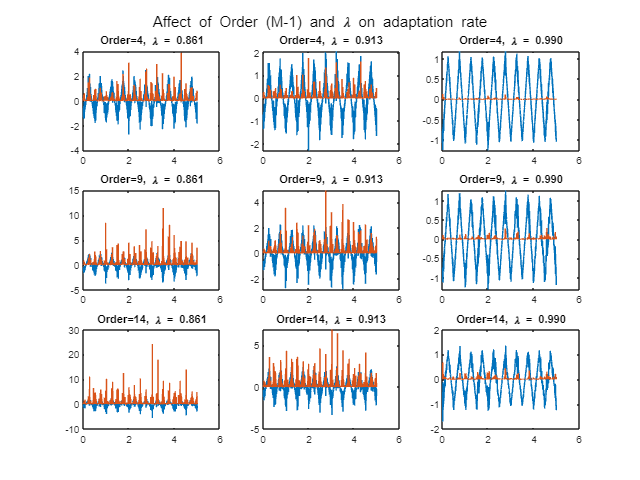

sgtitle("Affect of Order (M-1) and \lambda on adaptation rate");

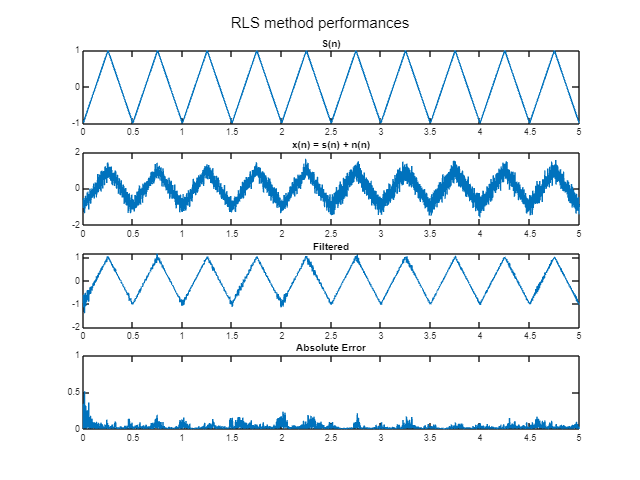

figure('Position', [100, 100, 800, 600]);
subplot(4, 1, 1); 
plot(t(best_M_RLS:end), s(best_M_RLS:end));
title("S(n)")

subplot(4, 1, 2); 
plot(t(best_M_RLS:end), x(best_M_RLS:end));
title("x(n) = s(n) + n(n)");

subplot(4, 1, 3); 
plot(t(best_M_RLS:end),best_constructed_signal_RLS);
title("Filtered");

subplot(4, 1, 4); 
plot(t(best_M_RLS:end), abs(s(best_M_RLS:end)-best_constructed_signal_RLS));
ylim([0 1]);
title("Absolute Error");

sgtitle("RLS method performances");

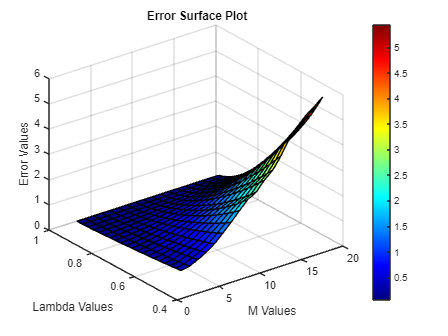

figure;
[M, Lambda] = meshgrid(3:20, lambdas);
surf(M, Lambda, errors_Matrix_RLS');

xlabel('M Values');
ylabel('Lambda Values');
zlabel('Error Values');
title('Error Surface Plot');
view(3);
colormap('jet');
colorbar;